# 1.4. Основы языка технических расчетов MATLAB

**Лекция**

## Ввод и удаление переменных (variables)

В тексте MATLAB-файла переменные определяются следующим образом:

x = 1
y = 2.34 

Точка с запятой в конце строки предотвращает вывод переменной при исполнении команды:

z = 48.2;

При этом в памяти хранятся все определённые в тексте программы переменные. Они отображены в области *Workspace *(Рабочая область):

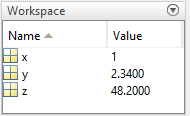

Имена переменных должны удовлетворять следующим условиям:

    ●  Допустимое количество символов в названии: от 1 до 63;

    ●  Имя должно состоять из комбинаций английских малых и больших букв (`a-z` и `A-Z`), цифр (`0-9`), и нижнего подчеркивания (`_`). 

    ●  Имя должно начинаться с латинской буквы

Примеры представлены в таблице:

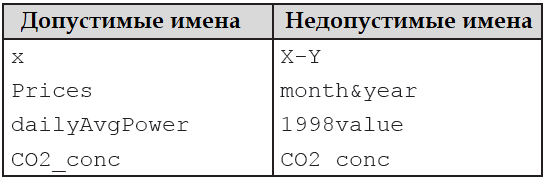

Большие и маленькие латинские буквы различаются интерпретатором MATLAB. Будьте внимательны к регистру! 

Вот пример трех разных переменных: 

spacex = 100
SPACEX = 20
spaceX = 40

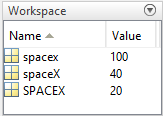

В текст также можно вставлять коментарии с помощью символа "`%`":

% это комментарий
comm = 31 % и это тоже комментарий
% spaceX = 42; этот код также не будет исполняться

Переменные удаляются следующим образом:

clear comm % удаление одной переменной
clear        % удаление всех переменных  

## Операции над переменными

Базовые арифметические операции:

a = (12 + 3*4)/6
b = a^3 + 2
b = 2*b/11

Основные математические функции:

x = sqrt(25) + log(11) - exp(log10(1324) + log2(1/64)) 
y = sin(pi/2)+ cos(x) + tan(1/2)
z = atan(x) - asin(0.8)/acos(0.99)

`log` - натуральный логарифм, `log10` - десятичный логарифм, `log2` - логарифм по основанию 2.

Тригонометрические функции, аргументами которых выступают углы, выраженные в градусах:

x = x + sind(90) - cosd(180) 
y = y - tand(45)

Также представлены гиперболические функции:

z = sinh(x) + cosh(y) + tanh(z)

Бесконечности и отсутствующие/неопределённые значения определяются как `Inf и NaN`:

Strange1 = -5/0
Strange2 = log(0)
Strange3 = Inf - Inf
Strange4 = NaN 

## Создание векторов

Векторы в MATLAB могут быть представлены в виде вектора-строки и вектора столбца.

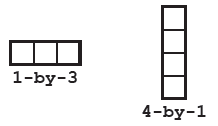

Переменные, рассмотренные ранее, формально, также являются векторами с размерностью 1х1.

Их можно создавать покомпонентно:

vector_13 = [1, 2, 3] % вектор записан в виде строки из чисел через запятые
vector_13_s = [1 2 3] % вектор записан в виде строки из чисел через пробелы
vector_31 = [1; 2; 3] % вектор записан в виде столбца из чисел

Создать вектор с известными начальными и конечными компонентами при известном приращении (шаге) можно так:

`Вектор-строка`` = Первый_элемент``:``Шаг``:``Конечный_элемент` 

c = 3:1:8 

Если вместо шага известно количество компонентов, вектор задается функцией 

`linspace(``Первый_элемент``,`` Конечный_элемент``,`` Количество_элементов``)`

d = linspace(2,3,6)

Вектор-строку можно превратить в вектор-столбец операцией транспонирования:

c.'
d.'

**Вектора со случайными** значениями компонентами могут быть созданы с помощью функций `rand``, ``randn``, ``randi``.` 

Аргументом этих функций является размерность. Например, случайной строке длиной `n `соответствует размерность `(1,n)`, а случайному столбцу того же размера `(n,1)`. Вопрос размерностей более углублённо рассмотрен в сл. лекции (2.1 "Матричные операции")

Функция `rand()` вызывает равномерное распределение на интервале (0,1):

rand(1,6)

Функция `randi([i_min, i_max])` вызывает равномерное распределение целых чисел на интервале `[i_min, i_max]` ("randi" - "rand integer"):

randi([2,18],1,6)

Функция `randn()` вызывает нормальное распределение с мат. ожиданием 0 и среднеквадратичным отклонением 1:

randn(1,6)

Операция **конкатенации** (соединения) двух векторов-строк и векторов-столбцов выполняется следующим образом:

conc_str = [vector_13 , d]
conc_stolb = [c'; vector_31]

Слова, как наборы символов, могут быть представлены в виде вектора-строки из символов:

char_1 = 'Преступление*'

К ним может быть также применена операция конкатенации:

char_2 = 'наказание';
char_3 = ' и ';
[char_1, char_3, char_2]

Также можно преобразовывать числа в текст с помощью команды `num2str`:

char_num = num2str(d(3))
[char_2,  ' стоит ', char_num, ' рубля']

## Доступ к компонентам вектора

Все компоненты вектора пронумерованы так (братите внимание, что нумерация вектора начинается с **единицы**):

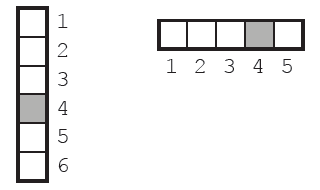

Обращаться к компонентам векторам следует следующим образом:

vector_13(2)

Компоненты вектора переопределяемы:

d(4) = d(3)+d(2)

К последнему компоненту вектора можно обращаться как к номеру **end:**

d(end) 
d(end-1)

Можно также вызывать сразу несколько компонентов вектора по их номерам: 

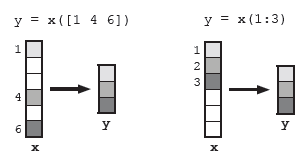

Пример:

d
d([1 4 3])
d(3:end-1)

Можно также заменять сразу несколько компонентов вектора одновременно:

Длина вставляемого элемента должна совпадать с длиной места, куда вставлять!

Можно заменять выбранные компоненты вектора на одно число: 

Удаление компонента вектора производится присвоением пустого компонента:

d_cut = d
d_cut(2) = []

## Операции над векторами

Векторы **одинаковой длинны** можно складывать, вычитать, а также складывать, вычитать, умножать и делить на числа:

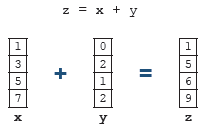                           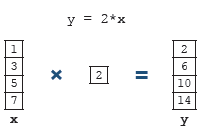

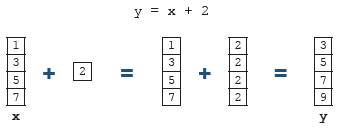

Пример:

e = (-2*c + 5*(d+1))/8

Для покомпонентного умножения двух векторов, а также покомпонентного деления и возведения в степень перед арифметическим символом ставится точка:

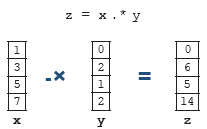

Пример:

f = (c.*d + d./c + c.^2).^e

Ко всем компонентам вектора можно применять математические функции:

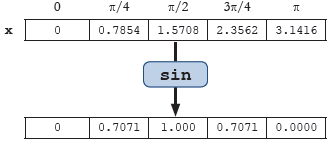

Пример:

g = 0:pi/4:pi;
sin_g = sin(g)
cos_g = cos(g)
exp_g = exp(g)
log_g = log(g+1)

## Встроенные функции над векторами

Рассмотрим некоторые встроенные функции над векторами на примере такого вектора:

NL_vect = log(0.5:0.25:3)

**Длина вектора** (количество компонент) находится с помощью функции `length`: 

length(NL_vect)

также может быть найдено **среднеарифметическое** и **медианное** значение с помощью функций `mean` и `median` соответственно:

mean(NL_vect)
median(NL_vect)

 Значение **максимального и минимального** компонента вектора, а также их номера определяются с помощью функций `min` и `max` соответственно: 

[min_f,min_id] = min(NL_vect)
[max_f,max_id] = max(NL_vect)

**Норма** порядка p находится с помощью известного выражения:

,

Эта функция реализована как `norm``(X,p):`

norm(NL_vect, Inf)  % p = Inf
norm(NL_vect, 8) 
norm(NL_vect, 2) % Евклидова норма, стоит по умолчанию
norm(NL_vect)

**Сумма** всех компонент вектора:

sum(NL_vect)

**Скалярное произведение** векторов:

dot(d, e)

**Векторное произведение** векторов (операция разрешена если размерность обоих векторов равна 3):

cross(d(1:3), e(1:3))

## Введение в построение графиков

Графики строятся с помощью функции `plot(``x,y``)`. Для корректной работы этой функции ей требуется два вектора одинаковой длины. Абсцисса каждой точки берётся из первого вектора, а ордината - из второго вектора с таким же порядковым номером:

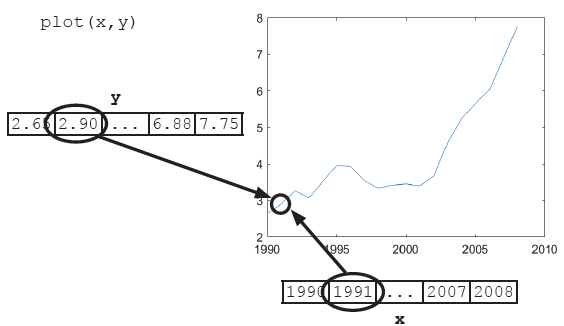

    Для иллюстрации работы функции plot рассмотрим следующий скрипт, отображающий синусоиду на заданном диапазоне:

n = 10:0.1:29.9 % задаётся диапазон
m = sin(n) 
plot(n,m)  

Если не вводить вектор абсцисс (в приведённом примере - вектор *n*), то по оси абсцисс будет откладываться порядковые номера компонентов вектора:

plot(m)

    Для добавления кривых на график используется команда `hold on`**:**

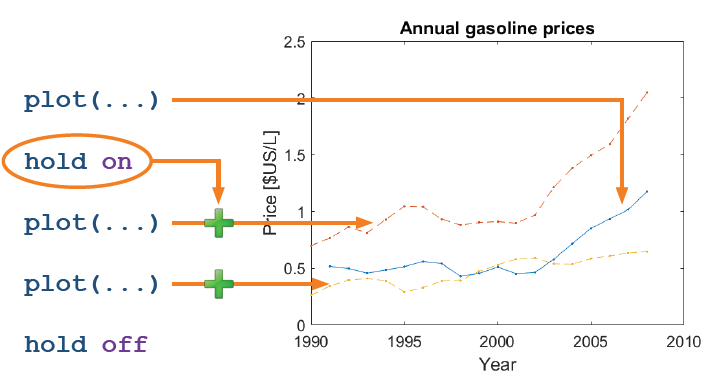

    Пример скрипта для построения нескольких кривых приведен ниже:

k = 0.2*log(n-3)    % формирование вектора для 2-й кривой
l = 0.5 * cos(n)    % формирование вектора для 3-й кривой
plot(n,m)       % отрисовка 1-й кривой
hold on
plot(n,k)       % отрисовка 2-1 кривой
plot(n,l)       % отрисовка 3-й кривой
hold off       

## Введение в оформление графиков

    С помощью функции `plot` можно рисовать не только линии. Рассмотрим, как отображать каждую точку желаемым маркером, как управлять цветом и стилем кривых. Более детально вопрос оформления графиков будет рассмотрен в лекции №4.1.

    В функцию `plot` можно добавлять свойства:

    Перечень этих свойств представлен в таблице:

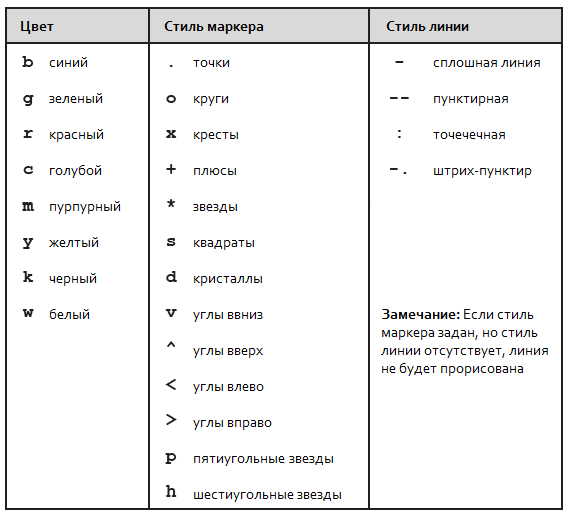

Пример использования свойств из приведённой таблицы : 

plot(n,m, 'ro')       % красные круги
hold on
plot(n,k, 'k-.')       % черная штрих-пунктирная линия
plot(n,l, 'bs-')       % синие квадраты и сплошная линия
hold off    

Подписи осей, и вставка названия реализуются с помощью функций `title`, `xlabel `и `ylabel`. В названия можно вставлять греческие буквы в стиле TeX (например `'\gamma' '\pi' '\omega'`):

plot(n,m)       % отрисовка кривой
title('Название графика')
xlabel('Абсцисса, \omegat')
ylabel('Ордината, \sigmaL^4')

Кривые можно подписать с помощью команды `legend`:

plot(n,m)       % отрисовка синуса
hold on
plot(n,k)       % отрисовка натурального логарифма
plot(n,l)       % отрисовка косинуса
hold off     

legend('синус', 'натуральный логарифм', 'косинус')